**Adrian Cristian Crisan**

**Link: **[https://drive.matlab.com/sharing/ea781bab-2362-4523-8028-3456101bbec7](https://drive.matlab.com/sharing/ea781bab-2362-4523-8028-3456101bbec7)

# Mobile robot short Project

Given the kown workspace: Sensors_Data.mat, Laser_Data_CV__d_b.mat and  Enviroment.png

Answer the following question:

## Pose estimation (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

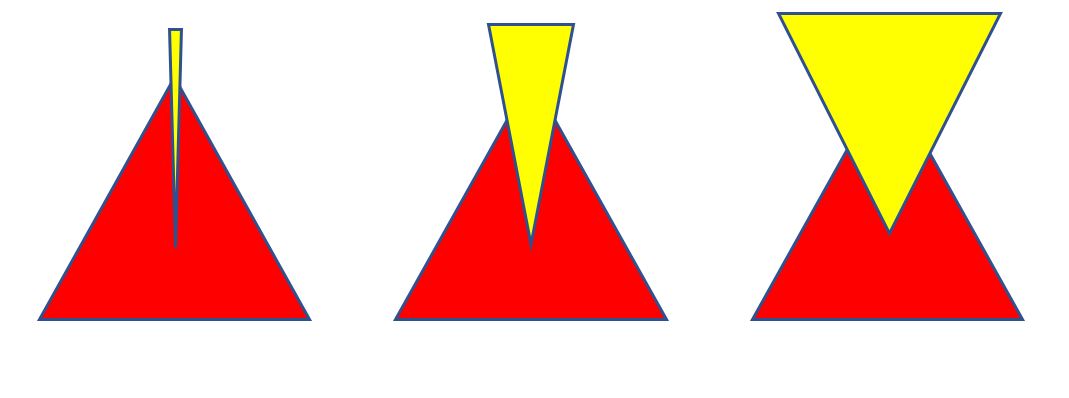

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

### 1-

#### a) Pose_theoric, asumme no noise.

#### b) Pose_estimation by adding noise in odometry.

clear
close all
clf
load("Sensors_Data.mat");

Tf = 60.08;
Ts = 0.02;
W = 0.52;
Gear_ratio = 100;
r = 0.1;

R_inc = right_angular_speed(:, 2) / Gear_ratio * r * Ts;
L_inc = left_angular_speed(:, 2) / Gear_ratio * r * Ts;
R_acu = [right_angular_speed(:, 1), cumsum(R_inc)];
L_acu = [left_angular_speed(:, 1), cumsum(L_inc)];

t=linspace(0,Tf,length(R_acu(:,2)))';
delta_d=(R_inc+L_inc)/2;
delta_t=(R_inc-L_inc)/W;

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2);
Initial_position=transl(Initial_pose);
Initial_orientation=-pi/2;

% Pose theoric
x(1) = Initial_position(1);
y(1) = Initial_position(2);
o(1) = Initial_orientation;
% Pose estimation
V = [3.61e-4 0; 0 9e-6];                 % Noise
n_d = V(1, 1);
n_t = V(2, 2);
x_est(1) = Initial_position(1);
y_est(1) = Initial_position(2);
o_est(1) = Initial_orientation;
for i=1:(length(t)-1)
    x(i+1) = x(i) + delta_d(i) * cos(o(i));
    y(i+1) = y(i) + delta_d(i) * sin(o(i));
    o(i+1) = o(i) + delta_t(i);

    x_est(i+1) = x_est(i) + (delta_d(i) + n_d) * cos(o(i) + n_t);
    y_est(i+1) = y_est(i) + (delta_d(i) + n_d) * sin(o(i) + n_t);
    o_est(i+1) = o(i) + delta_t(i) + n_t;
end

Pose_t = [x; y; o];
Pose_est = [x_est; y_est; o_est];

#### c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose.

Pk(:, :, 1) = eye(3);
for i=1:(length(t)-1)
    F_x = [1 0 -delta_d(i) * sin(o(i)); 0 1 delta_d(i) * cos(o(i)); 0 0 1];
    F_v = [cos(o(i)) 0; sin(o(i)) 0; 0 1];
    Pk(:, :, i+1) = F_x * Pk(:, :, i) * F_x' + F_v * [V(1) 0; 0 V(2)] * F_v';
end

### 2 -

#### a) x,y poses for both trajectories: theoric and estimated 

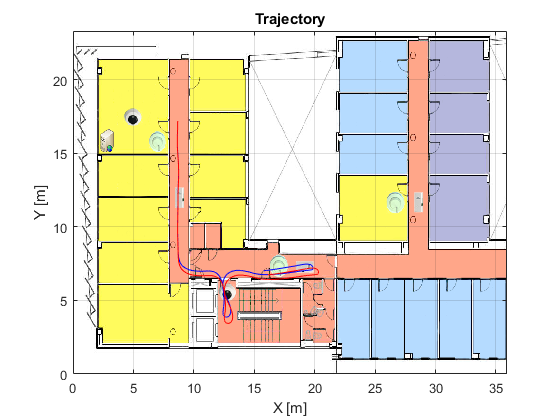

figure
I=imread('Enviroment.png');                 % Read blueprint
x_ima=[0 35.9];                             % Get blueprint position in frame
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);       % Display blueprint
axis xy
grid on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
hold on

plot(Pose_t(1,:), Pose_t(2,:), 'b')         % Display a) Pose_theoric
plot(Pose_est(1,:), Pose_est(2,:), 'r')     % Display b) Pose_estimation

#### b) Ellipses representing x,y uncertanty. Do it every 15-20 poses.

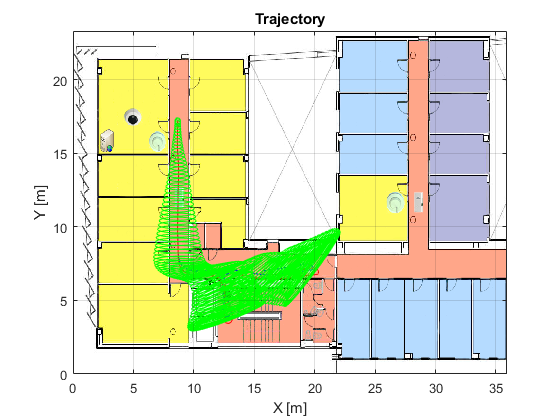

hold on
n = 20;
for i=1:n:(length(t)-1)
    e = Pk(:, :, i);
    plot_ellipse(e(1:2, 1:2)*0.05, [x(i) y(i)], 'g');
end
hold off

#### c) Represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

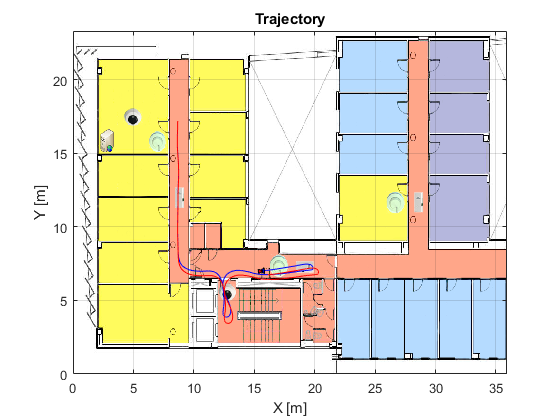

% Gets maximum det elipse uncertanty
max = 0;
for i=1:(length(t)-1)
    value = det(Pk(1:2, 1:2, i));
    if value > max
        max = value;
    end
end

% axis tight manual 
% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('2c_uncertanty_theoric.avi');
% open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
Triangle = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
for i=1:20:(length(t)-1)
    clf
    image(I,'XData',x_ima,'YData',y_ima);       % Display blueprint
    axis xy
    grid on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    hold on
    plot(Pose_t(1,:), Pose_t(2,:), 'b')         % Display a) Pose_theoric
    plot(Pose_est(1,:), Pose_est(2,:), 'r')     % Display b) Pose_estimation

    Triangle_unc = Triangle;
    e = Pk(:, :, i);
    aux1 = Triangle_unc(3, 2) * det(e(1:2, 1:2))/max;
    aux2 = Triangle_unc(1, 2) * det(e(1:2, 1:2))/max;
    Triangle_unc(3, 2) = aux1;
    Triangle_unc(1, 2) = aux2;

    Robot_pose = transl(x(i), y(i), 0) * trotz(o(i));
    Robot_final = Robot_pose * Robot';
    Triangle_final = Robot_pose * transl(0.5, 0, 0) * trotz(pi) * Triangle_unc';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'b');
    tri = patch(Triangle_final(1, :), Triangle_final(2, :), 'r');

    pause(0.9);

%     frame = getframe(gcf);
%     writeVideo(video, frame);
%     delete(rob);
%     delete(tri);
end

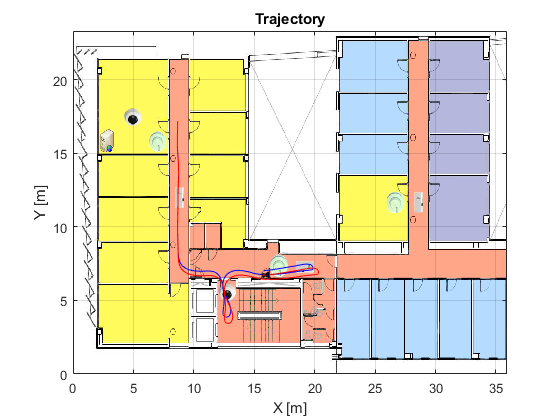

% close(video);
% 
% axis tight manual 
% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('2c_uncertanty_estimation.avi');
% open(video);
for i=1:20:(length(t)-1)
    clf
    image(I,'XData',x_ima,'YData',y_ima);       % Display blueprint
    axis xy
    grid on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    hold on
    plot(Pose_t(1,:), Pose_t(2,:), 'b')         % Display a) Pose_theoric
    plot(Pose_est(1,:), Pose_est(2,:), 'r')     % Display b) Pose_estimation

    Triangle_unc = Triangle;
    e = Pk(:, :, i);
    aux1 = Triangle_unc(3, 2) * det(e(1:2, 1:2))/max;
    aux2 = Triangle_unc(1, 2) * det(e(1:2, 1:2))/max;
    Triangle_unc(3, 2) = aux1;
    Triangle_unc(1, 2) = aux2;

    Robot_pose = transl(x_est(i), y_est(i), 0) * trotz(o_est(i));
    Robot_final = Robot_pose * Robot';
    Triangle_final = Robot_pose * transl(0.5, 0, 0) * trotz(pi) * Triangle_unc';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'b');
    tri = patch(Triangle_final(1, :), Triangle_final(2, :), 'r');
    
    pause(0.9);
 
%     frame = getframe(gcf);
%     writeVideo(video, frame);
%     delete(rob);
%     delete(tri);
end

% close(video);

## Laser data (10%)

Make a movie of laser data in Robot reference frame.

copy here the code of the last TODO ab out laser data. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

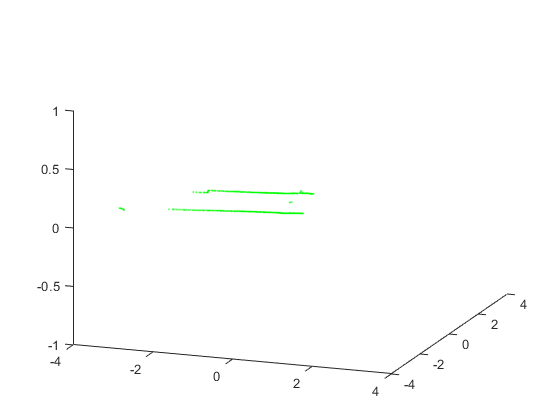

load('Laser_Data_CV__d_b.mat')
% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('2_mapping.avi');
% open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
visible = 0;
for k=1:6:(length(t)-1)
    clf
    Robot_pose = transl(x(k), y(k), 0) * trotz(o(k));
    Robot_final = Robot_pose * Robot';
    
    if (mod(k, 6) == 1)
        clear x2 y2
        count = 1;
        m = size(polar_laser_data);
        i = ceil(k/20.1611);
        for j=1:(m(2)-1)
            if polar_laser_data(i, j) / 1000 > 0
                alpha = (j-1) * 0.3515;
                alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
                x2(count) = (polar_laser_data(i, j) / 1000) * cos(alpha);
                y2(count) = (polar_laser_data(i, j) / 1000) * sin(alpha);
                count = count + 1;
            end
        end
    end

    scatter(x2, y2, 1, '.', 'green');
    view([20 20]);
    xlim([-4 4])
    ylim([-4 4])

    pause(0.9)
%     
%     frame = getframe(gcf);
%     writeVideo(video, frame);
%     delete(rob);
end

% close(video);

## Localization (40%)

Localize the Robot  by using the Similarity Transform. 

There are two asummtions :

### No correction of the trajectory is done.

1.- Make a 'log' with the following columns: time stamp, estimated noisy pose, number of Land-marks seen  and the errors.

% Ladmarks poses
LandMark = [ 7.934 16.431;...
              9.583 16.431;...
              9.584 13.444;...
              9.584 10.461;...
              7.973 10.534;...
              7.934  7.547;...
              9.584  6.654;...
             13.001  6.525;...
             17.007  8.136]';

% Analize simulation
clear m
m = 860;
Robot_pose=transl(x_est(m), y_est(m), 0) * trotz(o_est(m));
Robot_m=transl(Robot_pose);
Robot_pose_teo=transl(transl(x(m), y(m), 0) * trotz(o(m)));

% Read the laser
d_4=l_s_d(m,4);
b_4=l_s_b(m,4);
d_78=l_s_d(m,7:8);
b_78=l_s_b(m,7:8);

% Laser 2 Word
[x4,y4]=pol2cart(b_4(1,1),d_4(1,1));
[x7,y7]=pol2cart(b_78(1,1),d_78(1,1));
[x8,y8]=pol2cart(b_78(1,2),d_78(1,2));

L_m4_w=Robot_pose*[x4 y4 0 1]';
L_m7_w=Robot_pose*[x7 y7 0 1]';
L_m8_w=Robot_pose*[x8 y8 0 1]';
Innovation=[L_m4_w L_m7_w L_m8_w];
% % Innovation=[L_m7_w L_m8_w];

% Landmark needed
% LandMark = LandMark(1:2,7:8); % Only two LandMarks
LandMark = [LandMark(1:2, 4),LandMark(1:2,7:8)];

% Building Matrices
A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]];
end
B = []; % Build Matrix B
for i=1:size(Innovation, 2)
    B = [B; Innovation(1,i); Innovation(2,i)];
end

% Finding the error in pose
X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = -0.3639

ty_ST = X(4)

ty_ST = -0.2472

alpha_ST = atan2(X(2),X(1))

alpha_ST = 0.0071

% Cancel errors
Robot_error= transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST)*[Robot_m;1]

Robot_error =     9.5755
    7.2285
         0
    1.0000


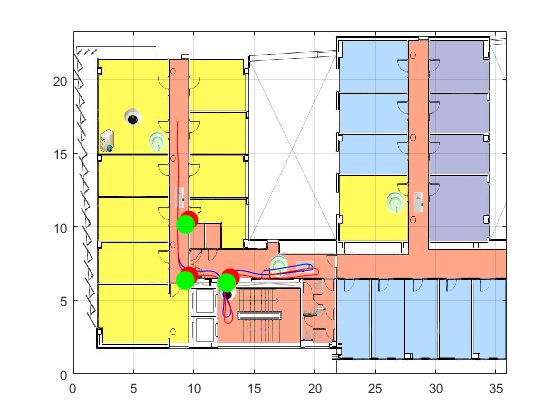


figure
% Display blueprint
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
grid on
% Display poses
plot(Pose_t(1,2:end), Pose_t(2,2:end), 'b');
plot(Pose_est(1,2:end), Pose_est(2,2:end), 'r');
% Display Landmarks
sz = 100;
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
scatter(Innovation(1,:), Innovation(2,:), 200, 'g','filled');

log1.time_stamp = t;             % Time stamp
log1.noiseD = n_d;               % Estimated noisy pose
log1.noiseTheta = n_t;
log1.number_landmarks = 4;       % Number of Land-marks seen
log1.tx_ST = tx_ST;              % Errors
log1.ty_ST = ty_ST;
log1.alpha_ST = alpha_ST;
log1.robot_error = Robot_error;

### Correct the noisy trajectory. 

To get an inspiration get familiar MR_SP_support.mlx

Pay attention to the relationship of the variables

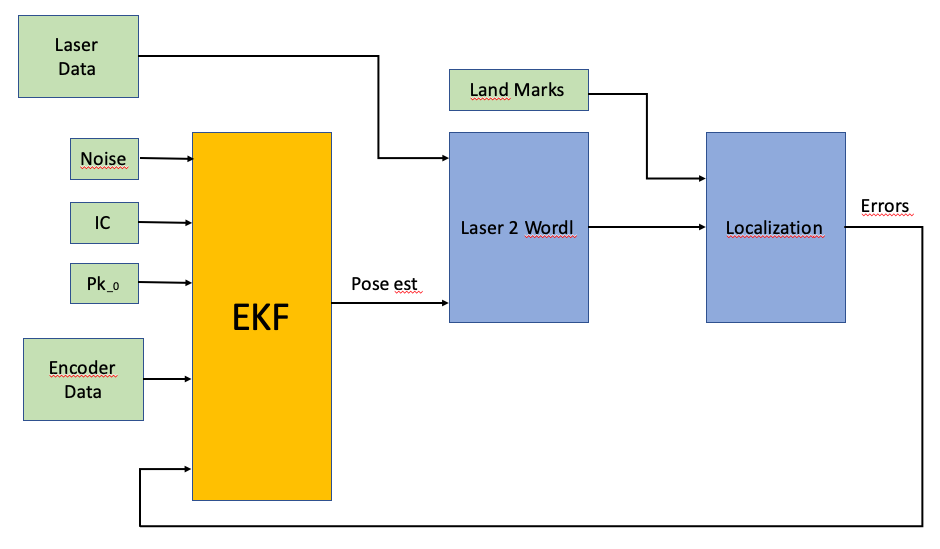

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) the noisy trajectory and the corrected trajectory.

2.- Make a 'log' with the following columns: time stamp, estimated noisy pose, corrected position, number of Land-marks,  and the errors.

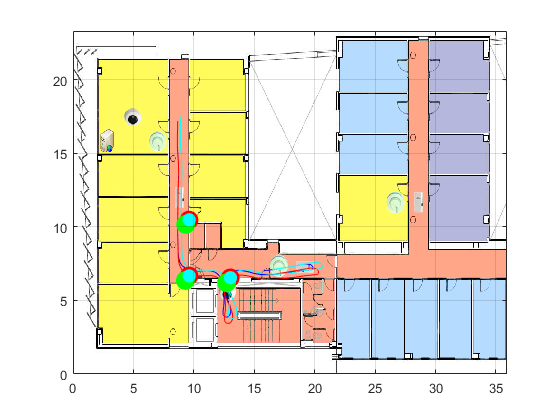

% Calculate the landmarks corrected
LandMark_corr = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * Innovation;
% LandMark_corr = LandMark_corr(1:2, 1:2);
LandMark_corr = LandMark_corr(1:2, :);

Pose_corr = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * [Pose_est; ones(1, length(Pose_est))];

figure
% Display blueprint
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
grid on
% Display poses
plot(Pose_t(1,2:end), Pose_t(2,2:end), 'b');
plot(Pose_est(1,2:end), Pose_est(2,2:end), 'r');
plot(Pose_corr(1,2:end), Pose_corr(2,2:end), 'c');
% Display Landmarks
sz = 100;
scatter(LandMark(1,:), LandMark(2,:), 200, 'r','filled');
scatter(Innovation(1,:), Innovation(2,:), 200, 'g','filled');
scatter(LandMark_corr(1,:), LandMark_corr(2,:), sz, 'c','filled');

log2.time_stamp = t;             % Time stamp
log2.noiseD = n_d;               % Estimated noisy pose
log2.noiseTheta = n_t;
log2.corrected_pos = Pose_corr;  % Corrected position
log2.number_landmarks = 4;       % Number of Land-marks seen
log2.tx_ST = tx_ST;              % Errors
log2.ty_ST = ty_ST;
log2.alpha_ST = alpha_ST;
log2.robot_error = Robot_error;

## Mapping (40%)

This is part of the last TODO.

### Walls

Draw the *'walls/obstacles'  seeing by* the laser data. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Make a movie erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

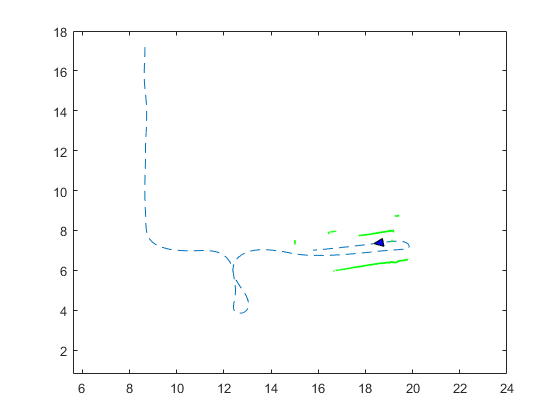

close all

% Ladmarks poses
LandMark = [ 7.934 16.431 0 1;...
              9.583 16.431 0 1;...
              9.584 13.444 0 1;...
              9.584 10.461 0 1;...
              7.973 10.534 0 1;...
              7.934  7.547 0 1;...
              9.584  6.654 0 1;...
             13.001  6.525 0 1;...
             17.007  8.136 0 1]';

% axis tight manual 
% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('3_mapping.avi');
% open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
visible = 0;
for k=1:3:(length(t)-1)
    clf
    plot(Pose_t(1,:), Pose_t(2,:), '--');
    xlim([5.6 24.0])
    ylim([0.8 18.0])
    hold on

    Robot_pose = transl(x(k), y(k), 0) * trotz(o(k));
    Robot_final = Robot_pose * Robot';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'b');
    
    if (mod(k, 6) == 1)
          clear x2 y2
        count = 1;
        m = size(polar_laser_data);
        i = ceil(k/20.1611);
        for j=1:(m(2)-1)
            if polar_laser_data(i, j) / 1000 > 0
                alpha = (j-1) * 0.3515;
                alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
                x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
                y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
                count = count + 1;
            end
        end
    end

    if mod(k, 20) == 0
        visible = 0;
        for i = 1:width(l_s_b)
            if visible == 0 && l_s_b(k, i) ~= 0
                P = LandMark(:, i);
                dist = sqrt( (x(k) - P(1))^2 + (y(k) - P(2))^2 );
                if dist <= 4
                    visible = 1;
                end  
            end
        end
    end

    if visible
        scatter(x2, y2, 1, '.', 'green');
    end

    pause(0.9)
    
%     frame = getframe(gcf);
%     writeVideo(video, frame);
%     delete(rob);
end

% close(video);

### Occupancy grid

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

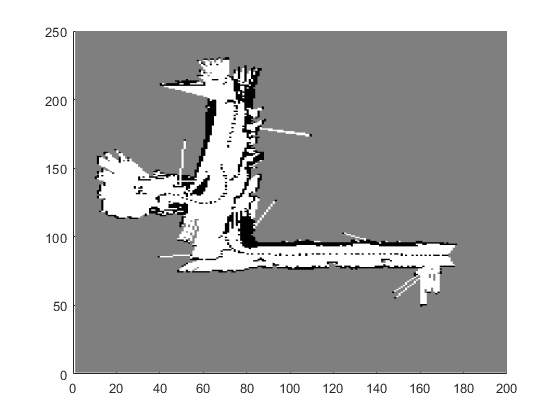

% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('3_Occupancy.avi');
% open(video);

resolution = 10;
A = ones(25*resolution, 20*resolution);
for p=20:20:(length(t)-1)
    clear x2 y2 o2
    i = ceil(p/20.1611);
    count = 1;
    m = size(polar_laser_data);
    for j=1:(m(2)-1)
        if polar_laser_data(i, j) / 1000 > 0
            alpha = (j-1) * 0.3515;
            alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
            x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
            y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
            o2(count) = alpha;
            count = count + 1;
        end
    end
    
    for j = 1:(count-1)
        P_w = transl(0, 0, 0) * trotz(0) * [x2(j) y2(j) 0 1]';
        l_xy = bresenham([x(p)*resolution y(p)*resolution], round([P_w(1)*resolution, P_w(2)*resolution]));
        L=height(l_xy);
        for k=1:L
            if l_xy(k, 1) > 0 && l_xy(k, 2) > 0
                if k == L
                    A(l_xy(k, 1), l_xy(k, 2)) = 0;
                else
                    A(l_xy(k, 1), l_xy(k, 2)) = 2;
                end
            end
        end
    end
    h = pcolor(A);
    h.EdgeColor = 'none';
    axis xy
    xlim([0 20*resolution]);
    ylim([0 25*resolution]);
    colormap(gray(3))
    pause(0.9)

%     frame = getframe(gcf);
%     writeVideo(video, frame);
end

% close(video);